# Tutorial 3: Running Inverse Kinematics in CASPR

This tutorial shows how to run inverse kinematics through two approaches:

- InverseKinematicsSimulator

- Writing your own time loop

## Load the robot and trajectory (required for both approaches)

Load a robot as shown in `tutorial_load_robot.mlx `and` tutorial_load_trajectory.mlx`

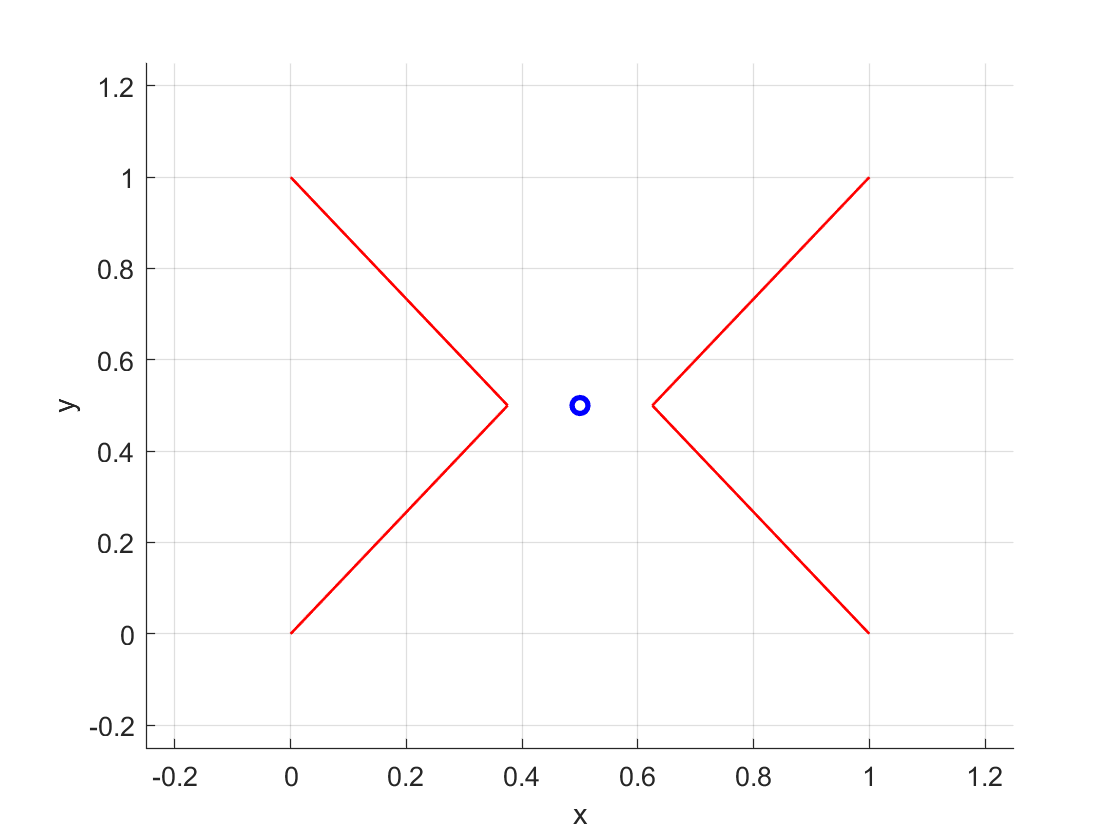

model_config = ModelConfig('Example planar XY');
cdpr_model = model_config.getModel('basic');
trajectory = model_config.getJointTrajectory('example_quintic');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

## Using the InverseKinematicsSimulator

The `InverseKinematicsSimulator` provides the simplest way to run a "standard" inverse kinematics simulation for a defined trajectory. 

First, create the simulator object using the robot model

ik_sim = InverseKinematicsSimulator(cdpr_model);

Next, run the simulator on a particular trajectory

ik_sim.run(trajectory);

[INFO] Time : 0.000000
[INFO] Time : 0.010000
[INFO] Time : 0.020000
[INFO] Time : 0.030000
[INFO] Time : 0.040000
[INFO] Time : 0.050000
[INFO] Time : 0.060000
[INFO] Time : 0.070000
[INFO] Time : 0.080000
[INFO] Time : 0.090000
[INFO] Time : 0.100000
[INFO] Time : 0.110000
[INFO] Time : 0.120000
[INFO] Time : 0.130000
[INFO] Time : 0.140000
[INFO] Time : 0.150000
[INFO] Time : 0.160000
[INFO] Time : 0.170000
[INFO] Time : 0.180000
[INFO] Time : 0.190000
[INFO] Time : 0.200000
[INFO] Time : 0.210000
[INFO] Time : 0.220000
[INFO] Time : 0.230000
[INFO] Time : 0.240000
[INFO] Time : 0.250000
[INFO] Time : 0.260000
[INFO] Time : 0.270000
[INFO] Time : 0.280000
[INFO] Time : 0.290000
[INFO] Time : 0.300000
[INFO] Time : 0.310000
[INFO] Time : 0.320000
[INFO] Time : 0.330000
[INFO] Time : 0.340000
[INFO] Time : 0.350000
[INFO] Time : 0.360000
[INFO] Time : 0.370000
[INFO] Time : 0.380000
[INFO] Time : 0.390000
[INFO] Time : 0.400000
[INFO] Time : 0.410000
[INFO] Time : 0.420000
[INFO] Time

Finally, the simulator can plot the results, such as the cable lengths:

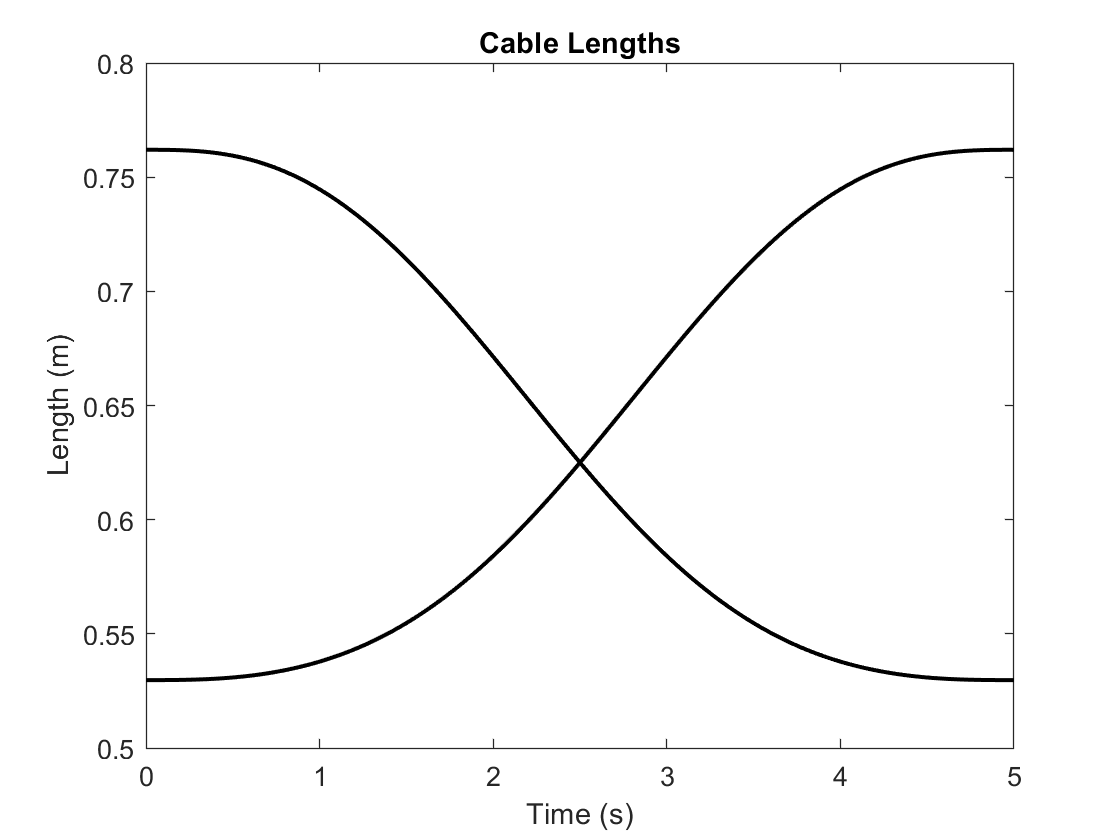

ik_sim.plotCableLengths();

Or the velocity of the cable lengths:

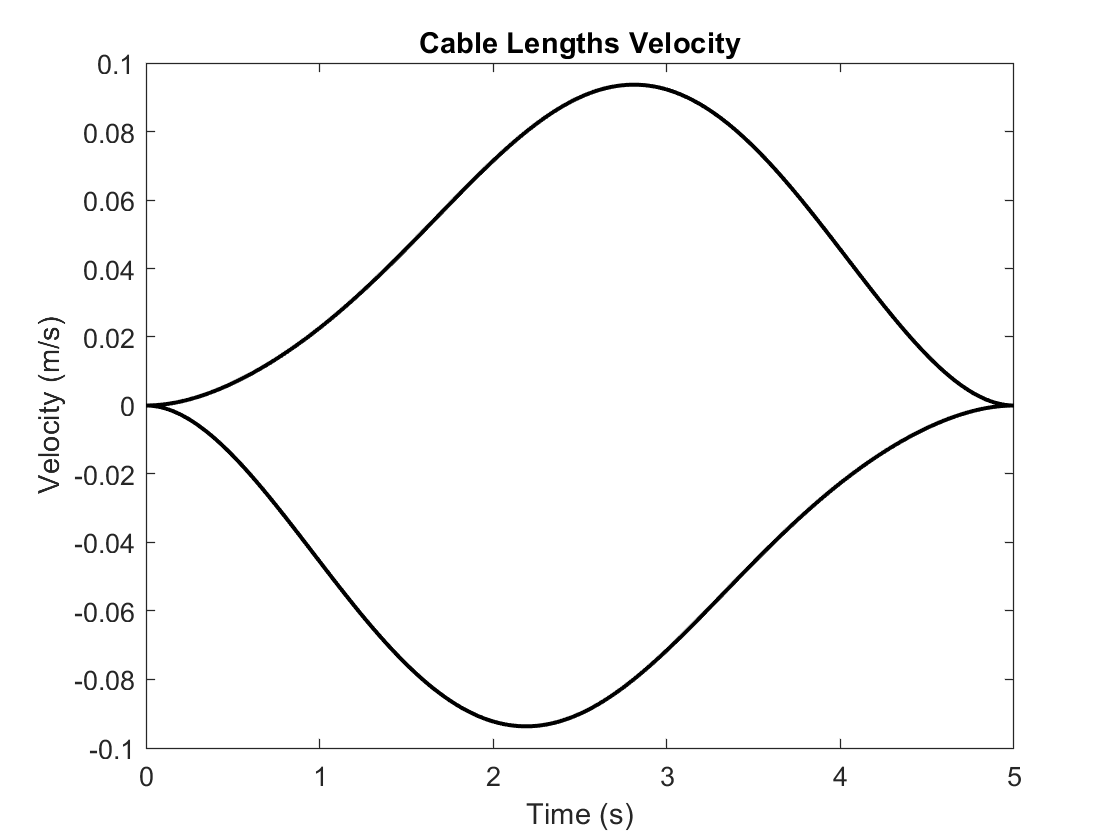

ik_sim.plotCableLengthsVelocity();

It can also plot the joint space information (like trajectories):

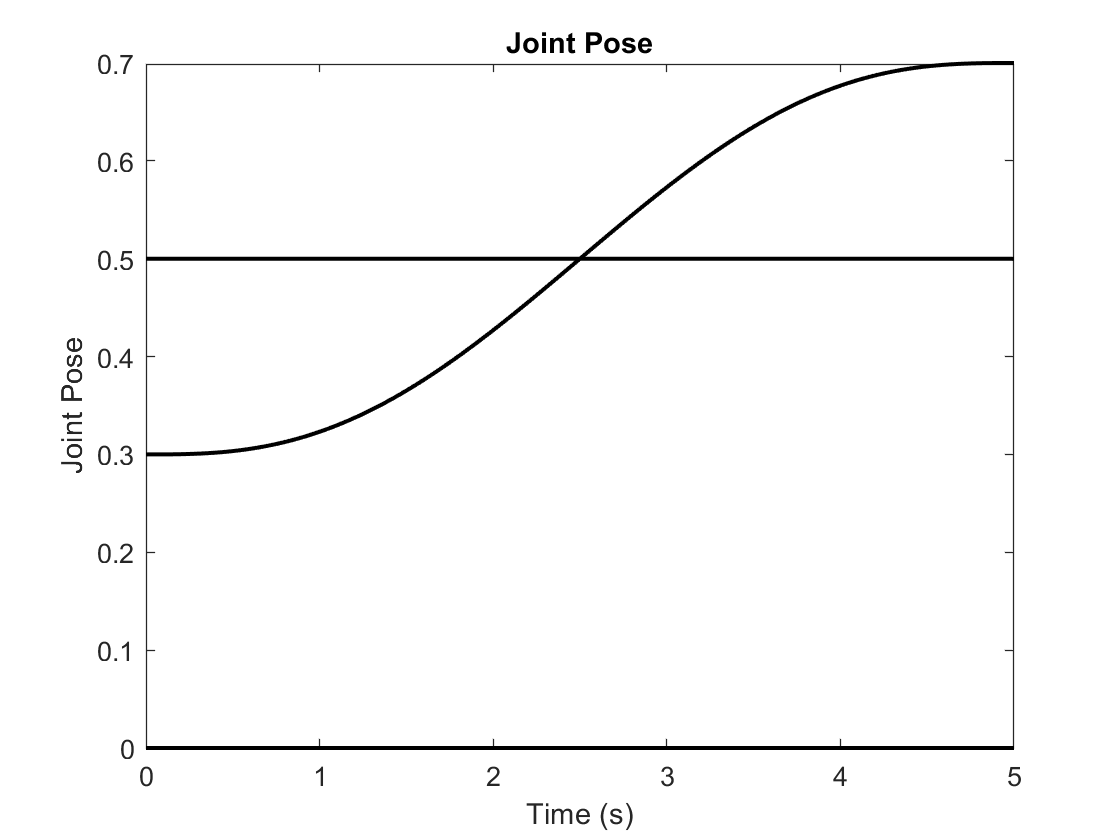

ik_sim.plotJointPose();

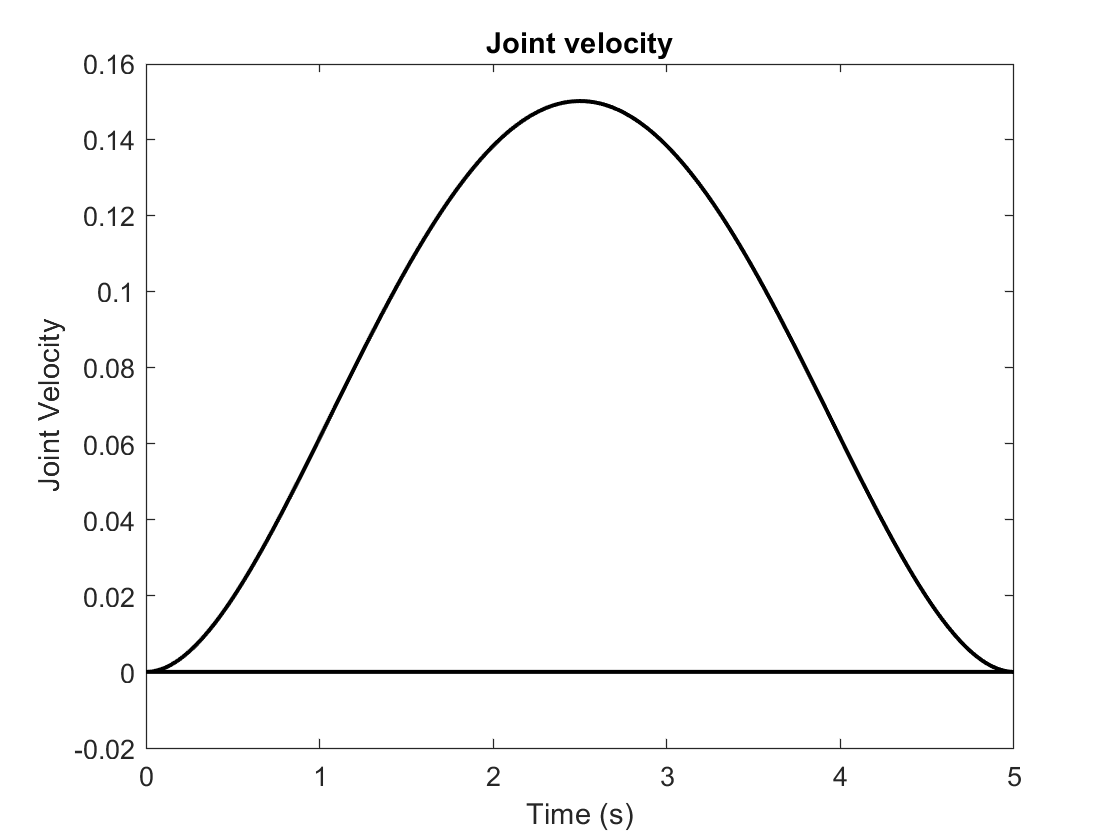

ik_sim.plotJointVelocity();

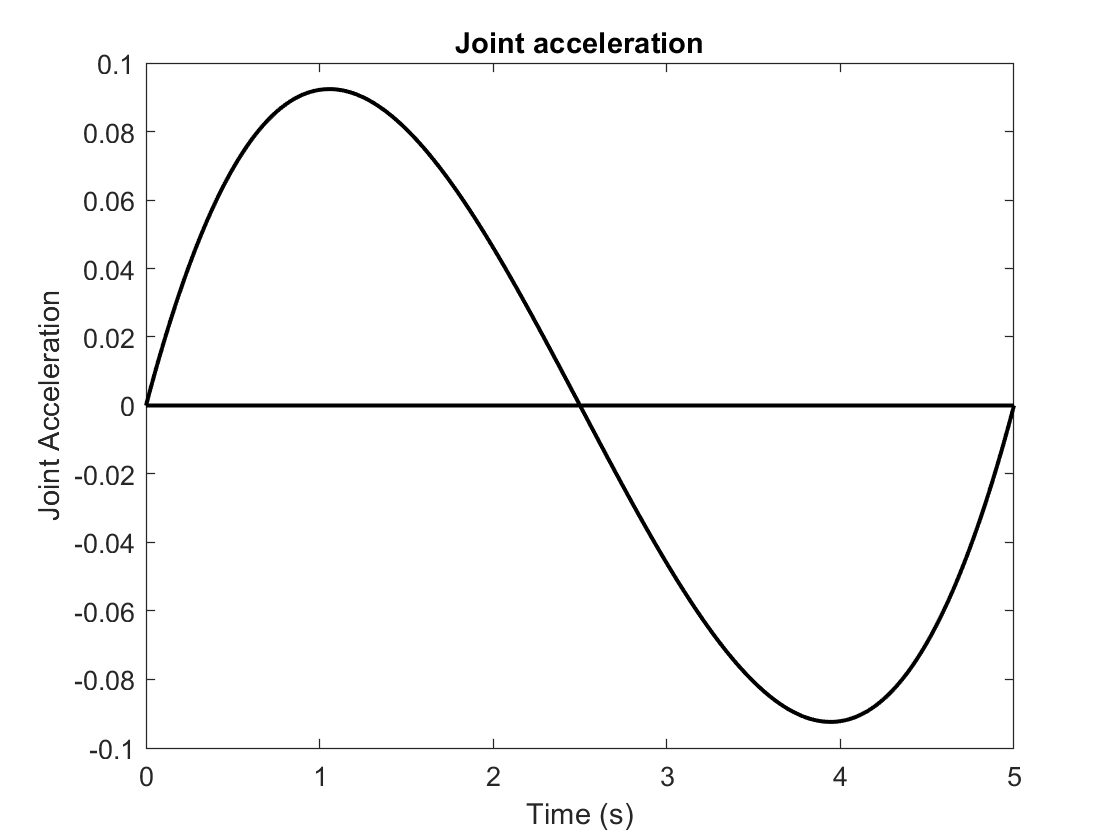

ik_sim.plotJointAcceleration();

And even the position, velocity and acceleration of the centre of gravity (CoG):

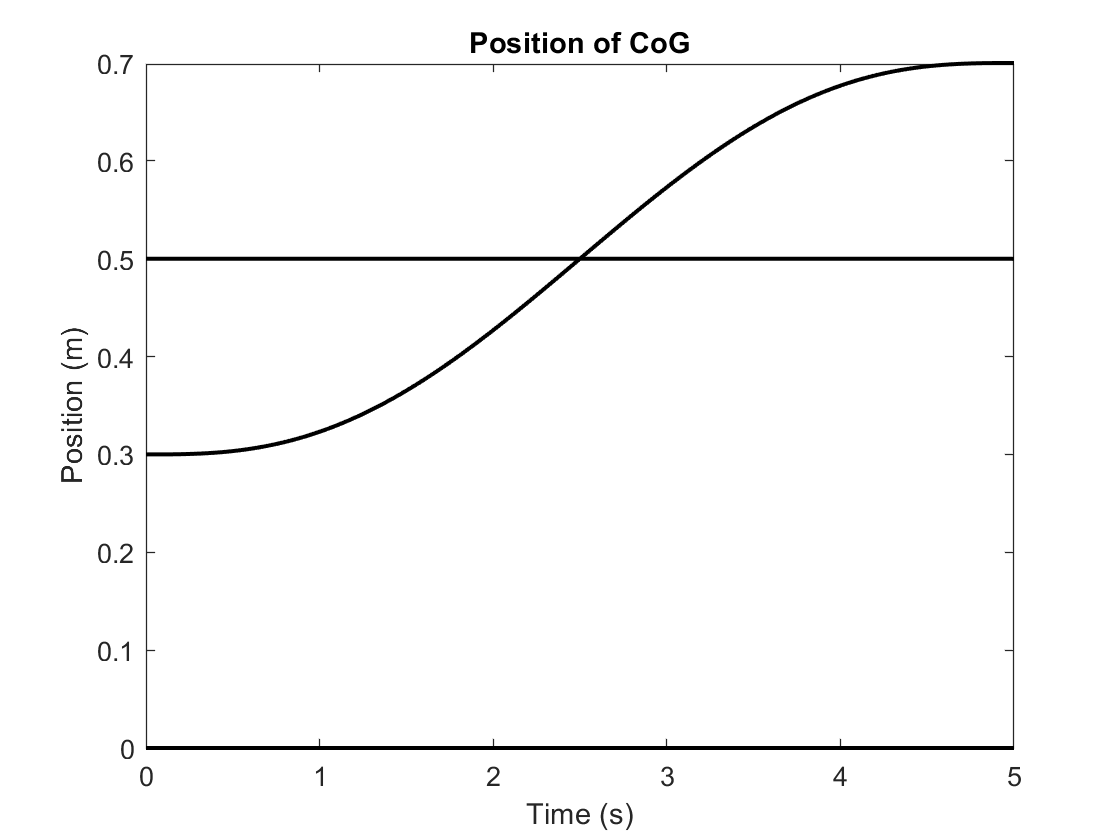

ik_sim.plotBodyCoG();

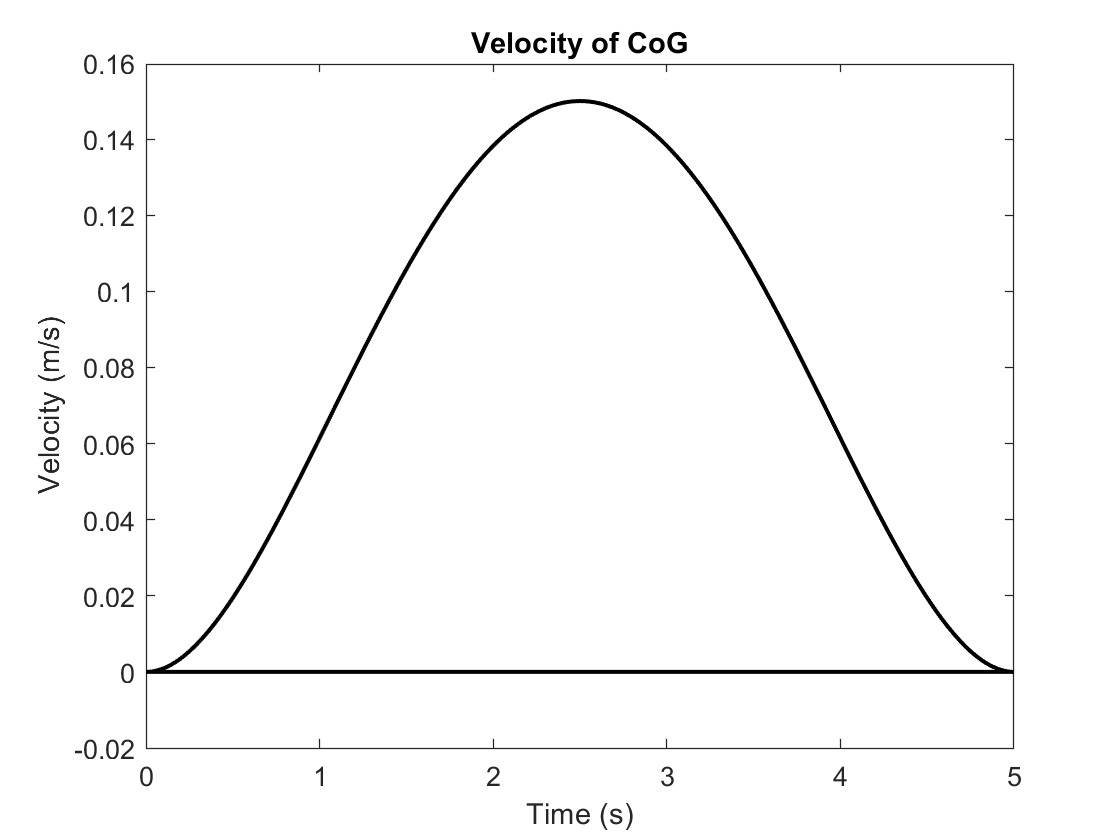

ik_sim.plotBodyCoGVelocity();

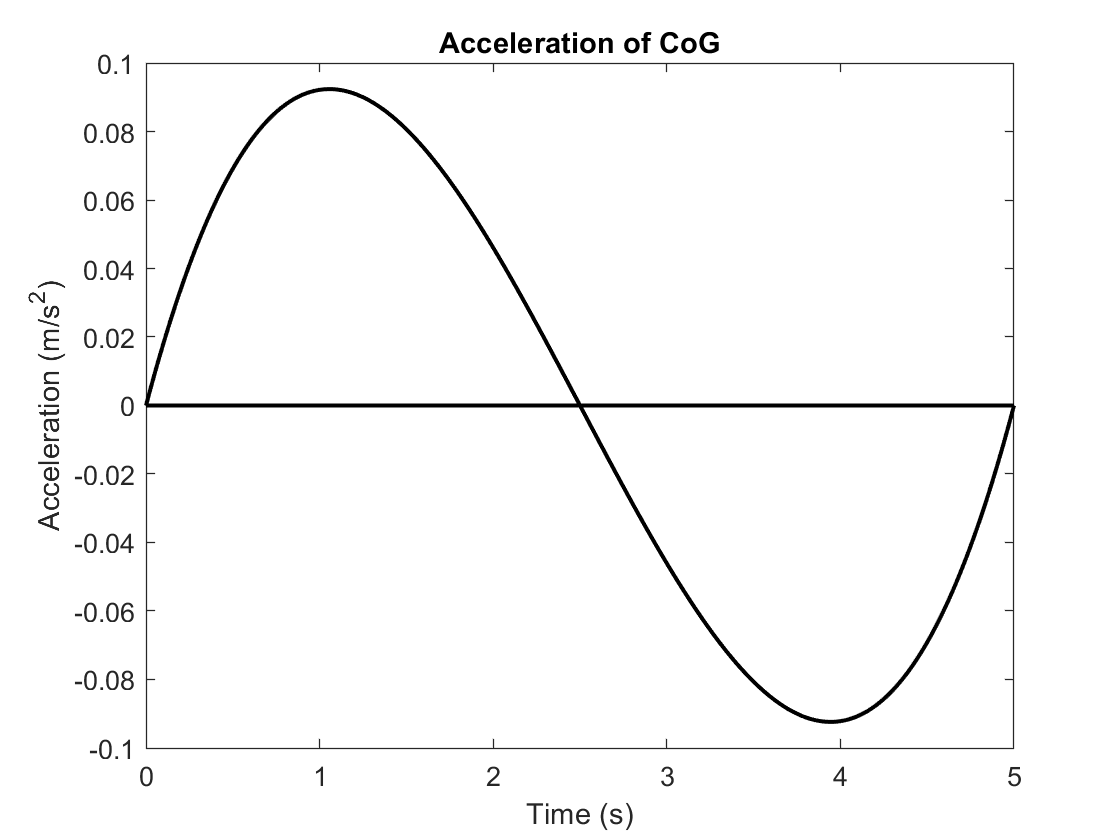

ik_sim.plotBodyCoGAcceleration();

## Writing your own time loop

If you want more control over what is happening or customise the inner-workings during the simulation, it is recommended for you to write your own time loop to perform the inverse kinematics. The following simple example is basically what happens within the `InverseKinematicsSimulator`.

First, create the variables (pre-allocate memory) required to store the solution from the inverse kinematics (cable lengths and cable lengths velocity):

ik_lengths = zeros(cdpr_model.numCables, length(trajectory.timeVector)); % Each column is the solution at each time step
ik_lengths_vel = zeros(cdpr_model.numCables, length(trajectory.timeVector));

Next, loop through the trajectory as a function of time:

for t = 1:length(trajectory.timeVector)

    The main step within the time loop is to update the model using the joint trajectory's pose, velocity and acceleration at this time instance (and assuming the external wrench is zero)

    cdpr_model.update(trajectory.q{t}, trajectory.q_dot{t}, trajectory.q_ddot{t}, zeros(cdpr_model.numDofs, 1));

    The model information, including the cable lengths and cable lengths velocity, are automatically updated and hence can be stored.

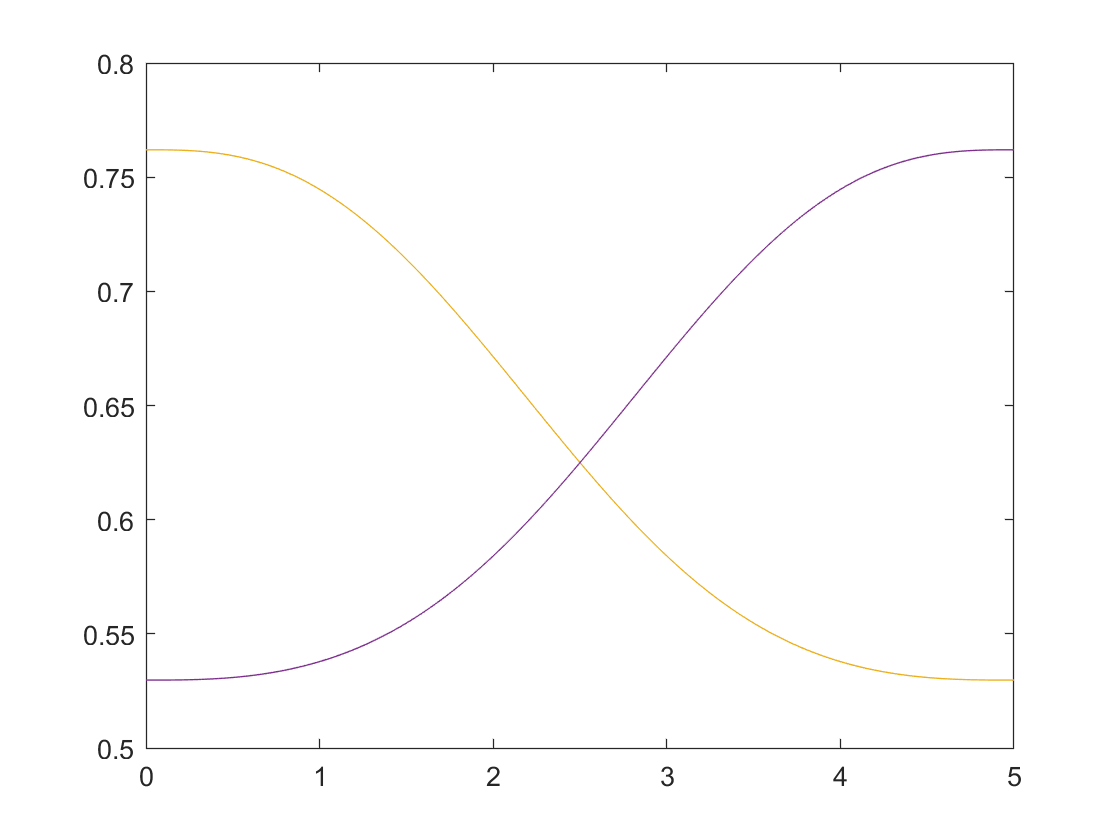

    ik_lengths(:,t) = cdpr_model.cableLengths;

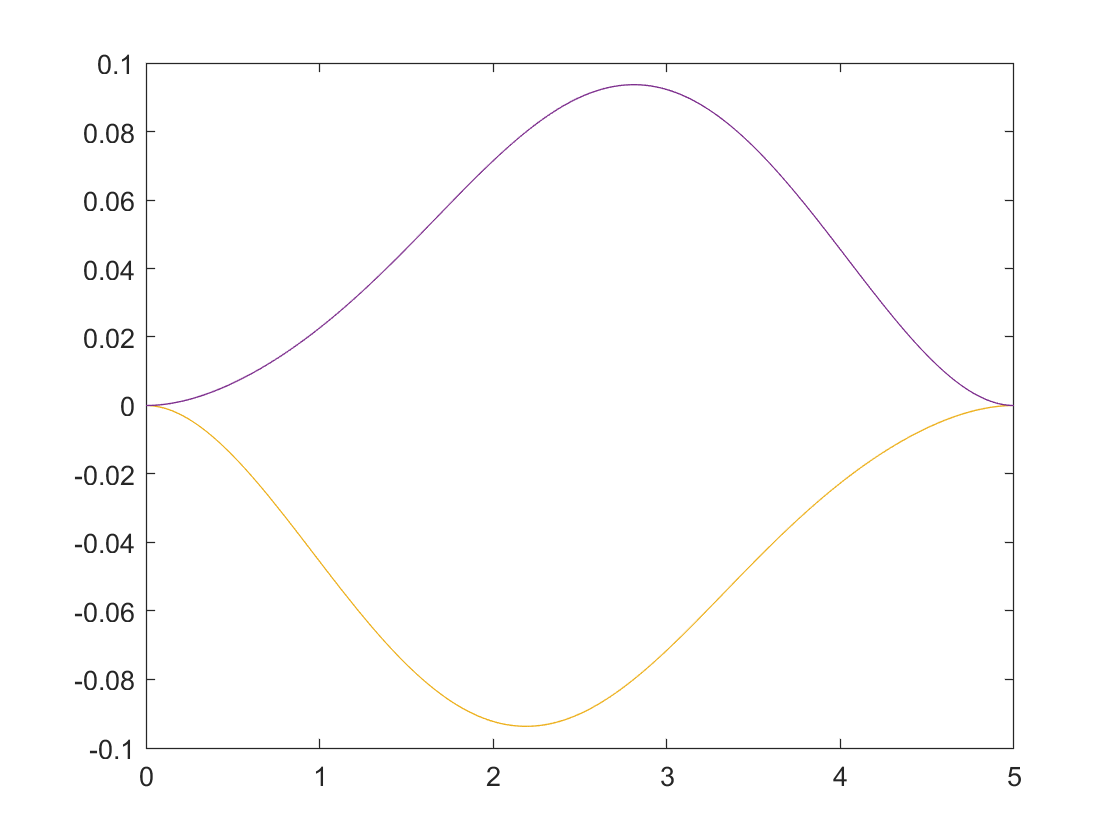

    ik_lengths_vel(:,t) = cdpr_model.cableLengthsDot;
end

The results can be plotted the way you desire yourself.

figure; 
plot(trajectory.timeVector, ik_lengths);
figure; 
plot(trajectory.timeVector, ik_lengths_vel);